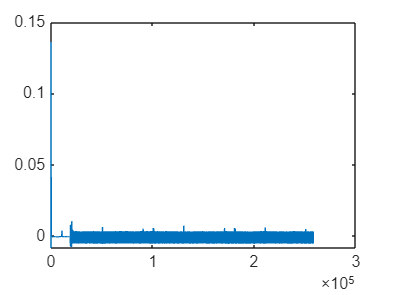

%% 0) Read captured data, skip first 100 samples
rec = read_float_binary('TEST_OOK_NOGAIN.bin')';
%rec = -1*rec(101 : end);  % discard early noise samples

rec = (rec-mean(rec(1000:end)))*-1;


figure
plot(rec)



% %% 1) Define passband preamble for correlation
% Fs            = 2e6;      % Sample rate
% Rb            = 1e3;      % Bit rate
% Fc            = 1e5;      % Carrier frequency
% samplesPreamb = 100;      % 100 samples per preamble bit
% preambleBits  = [1,1,1,1, 0,0,0,0, 1,0,1,0, 1,1,0,0];  % 16 bits
% preambleBase  = repelem(preambleBits, samplesPreamb); % length = 1600
% t             = (0 : length(preambleBase)-1)/Fs;
% carrier       = cos(2*pi*Fc*t);
% passbandPreamble = preambleBase .* carrier;  % reference for correlation
lenPreamble   = length(passbandPreamble);    % 1600


% Suppose you have:
%   modulatedSignal = <16-bit preamble, each bit upsampled 100 times, length 1600>
%   rxSignal        = <your captured signal from hardware, presumably >1600 samples>
rxSignal = (rec-mean(rec(1000:end)))*-1;

% Call the function
[startIdx, corrVal, lags] = findPreambleStart(rxSignal, passbandPreamble);

% Now 'startIdx' should be the sample index in 'rxSignal' 
% where the preamble aligns best with 'modulatedSignal'.
fprintf('Estimated preamble start index = %d\n', startIdx);

Estimated preamble start index = 19042


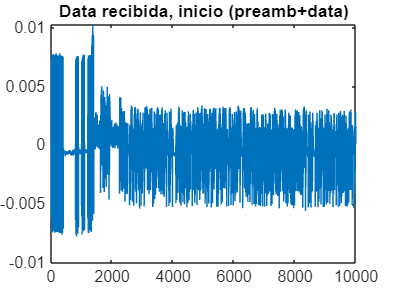


preambleStart = startIdx;

figure
plot(rec(startIdx:startIdx+10000))
title("Data recibida, inicio (preamb+data)")



%% 3) Parse out the pilot and data blocks by *length* in samples
% From your Tx code:
%   pilotLen = 32 bits => after RRC+H => ~ (32*10 + filterLen -1) + length(H)-1 ...
%   dataLen  = 24717 bits => similarly convolved => big number
% 
% To avoid confusion, we can replicate the EXACT lengths from the transmitter. 
% Or, for simplicity, define them as:
%   pilotConvLen = length of pilotConv
%   dataConvLen  = length of dataConv
%
% Let’s replicate the same logic:

% RRC filter
rolloff       = 0.25;
span          = 6;
samplesPerSym = 50;
rcFilter      = rcosdesign(rolloff, span, samplesPerSym, 'sqrt');
filtDelay     = (length(rcFilter)-1)/2;   % e.g. 30 if length(rcFilter)=61

% Pilot block length:
pilotBitsLen   = 32;                    % Tx used 32 bits
pilotUpLen     = pilotBitsLen*samplesPerSym; % 320
pilotRRCLen    = pilotUpLen + length(rcFilter) - 1;   % 320 + 61 - 1= 380
% After trimming Tx tail (filtDelay on each side) => 380 - 2*filtDelay => 380 - 60= 320
% Then convolved w/ H => + (length(H)-1). 
% So the final pilotConv length is 380 + (length(H)-1) if no Tx tail trimming,
% or 320 + (length(H)-1) if Tx trimmed. 
% Let's assume the code used "pilotRRC = pilotRRC(filtDelay+1 : end-filtDelay)" => that yields 380-60=320, 
% so pilotConvLen = 320 + (length(H)-1).
%
% We'll read H from file or assume in workspace:
%load('Final_response.mat');  % H
pilotConvLen = 320 + (length(H)-1);

% Data block length:
dataBitsLen   = 24717;
dataUpLen     = dataBitsLen*samplesPerSym;          % 247170
dataRRCLen    = dataUpLen + length(rcFilter) - 1;   % 247170 + 61 -1= 247230
% If Tx trimmed filter tails => 247230 - 2*filtDelay = 247230 - 60= 247170
% => dataConvLen = 247170 + (length(H)-1).
dataConvLen = 247170 + (length(H)-1);

% Indices in 'rec'
idxPilotStart = preambleStart + lenPreamble;              % after 1600 preamble samples
idxPilotEnd   = idxPilotStart + pilotConvLen - 1;
idxDataStart  = idxPilotEnd + 1;
idxDataEnd    = idxDataStart + dataConvLen - 1;

% Safety checks
if idxDataEnd > length(rec)
    warning('Recorded signal shorter than expected. Truncating data block.');
    idxDataEnd = length(rec);
end


% Extract
rxPilotWithH = rec(idxPilotStart : idxPilotEnd);
rxDataWithH  = rec(idxDataStart  : idxDataEnd);





%% 4) Matched filter + downsample for OOK pilot & data
% OOK baseband with RRC => same as Tx filter
% Because Tx did upsample->RRC->(trim)->conv(H),
% now we apply "matched filter" with the same RRC:
pilotFilt = filter(rcFilter, 1, rxPilotWithH);
pilotFilt = pilotFilt(filtDelay+1 : end-filtDelay);  % remove filter tails
pilotSyms = downsample(pilotFilt, samplesPerSym);

dataFilt = filter(rcFilter, 1, rxDataWithH);
dataFilt = dataFilt(filtDelay+1 : end-filtDelay);
dataSyms = downsample(dataFilt, samplesPerSym);



%% 5) LS Equalization using pilot (±1 BPSK)
% BPSK means pilot bits mapped as 0->-1, 1->+1 at Tx
% We must replicate EXACT pilot bits from Tx to do LS training.
%
% For example, if Tx had:
%   pilotBits = randi([0,1], 32,1);
%   pilotSyms = 2*pilotBits -1;
% here we do the same. Or use a known pattern.
%
% We'll do a known seed for demonstration:
rng(2025,'twister');                % *same seed* as Tx
pilotBits_tx = randi([0,1], pilotBitsLen,1);
pilotSyms_tx = 2*pilotBits_tx -1;   % BPSK ±1

% We have pilotSyms_rx in 'pilotSyms'. 
% Let's do an M-tap FIR for LS
M = 5;
Npilot = min(length(pilotSyms), length(pilotSyms_tx));
nTrain = Npilot - M + 1;
if nTrain < 1
    error('Not enough pilot symbols for M=%d tap LS filter.', M);
end

X = zeros(nTrain, M);
d = zeros(nTrain, 1);
for i = 1:nTrain
    X(i,:) = pilotSyms(i+M-1 : -1 : i).';
    d(i)   = pilotSyms_tx(i+M-1);
end

w = (X'*X)\(X'*d);  % LS solution


%% 6) Apply LS filter to data syms
rxDataEq_full = conv(dataSyms, flipud(w), 'full');
rxDataEq = rxDataEq_full(M : end);  % align

% The data block is 24717 bits => 24717 BPSK symbols
% Might be truncated if short
validDataLen = min(length(rxDataEq), dataBitsLen);
rxDataEq = rxDataEq(1:validDataLen);

%% 7) Hard decision for BPSK (±1)
% If real>0 => 1, else => 0
demodBits = real(rxDataEq) > 0;

% We also must replicate EXACT data bits from Tx
rng(2025,'twister');  % same seed as Tx for data
dummy    = randi([0,1], 32,1); % skip pilot draws if Tx used same call
dataBits_tx = randi([0,1], dataBitsLen,1);

txBitsRef = dataBits_tx(1:validDataLen);
numErrors = sum(demodBits(:) ~= txBitsRef(:));
BER = numErrors / validDataLen;

fprintf('\n--- BPSK Reception Summary ---\n');


--- BPSK Reception Summary ---


fprintf('Preamble Start index = %d\n', preambleStart);

Preamble Start index = 19042


fprintf('Data symbols used    = %d\n', validDataLen);

Data symbols used    = 4732


fprintf('Number of errors     = %d\n', numErrors);

Number of errors     = 2346


fprintf('BER                  = %.4g\n', BER);

BER                  = 0.4958


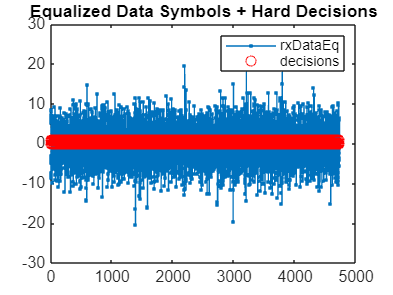


figure;
plot(real(rxDataEq), '.-'); hold on;
plot(demodBits*1.1, 'ro');  % overlay decisions
title('Equalized Data Symbols + Hard Decisions');
legend('rxDataEq','decisions');


function v = read_float_binary (filename, count)

  %% usage: read_float_binary (filename, [count])
  %%
  %%  open filename and return the contents, treating them as
  %%  32 bit floats
  %%

  m = nargchk (1,2,nargin);
  if (m)
    usage (m);
  end

  if (nargin < 2)
    count = Inf;
  end

  f = fopen (filename, 'rb');
  if (f < 0)
    v = 0;
  else
    v = fread (f, count, 'float');
    fclose (f);
  end
end


function [startIndex, corrVec, lagVec] = findPreambleStart(rxSignal, preambleSignal)
% FINDPREAMBLESTART Finds where a known preamble begins in a received signal
%   [startIndex, corrVec, lagVec] = findPreambleStart(rxSignal, preambleSignal)
%
% INPUTS:
%   rxSignal       : The full received signal (row or column vector).
%   preambleSignal : The known preamble samples (row or column vector).
%
% OUTPUTS:
%   startIndex : The estimated index in rxSignal where the preamble starts.
%   corrVec    : The cross-correlation array (for optional debugging/plotting).
%   lagVec     : The corresponding lags vector from xcorr.

    % Ensure column vectors for consistency
    rxSignal       = rxSignal(:);
    preambleSignal = preambleSignal(:);

    % 1) Cross-correlation
    [corrVec, lagVec] = xcorr(rxSignal, preambleSignal);

    % 2) Find the lag where correlation magnitude is maximum
    [~, idxMax] = max(abs(corrVec));

    bestLag = lagVec(idxMax);

    % 3) Convert that lag to a start index in rxSignal
    %
    %   If bestLag >= 0:
    %       preamble starts at sample (bestLag + 1)
    %   If bestLag < 0, the best alignment is "before" rxSignal's first sample, 
    %   so effectively the start is near index 1. We'll clamp it to avoid negative indexing.
    %
    startIndex = bestLag + 1;  % +1 because MATLAB is 1-based indexing

    if startIndex < 1
        startIndex = 1;
    end

    % Optionally, you can check if the entire preamble fits in rxSignal:
    if startIndex + length(preambleSignal) - 1 > length(rxSignal)
        warning('Preamble extends beyond the length of rxSignal. Check capture length.');
    end
end